clear

addpath("matlab_functions\")

#### Read MFD data

[B0,freqs1,defects] = readMFD('data/B_defectless.txt');
assert(isempty(defects))

[B ,freqs2,defects] = readMFD('data/B_defect_circ2mm.txt');
assert(all(freqs1==freqs2))

freqs = freqs1;
delta_B = B - B0;

% currently use only one frequency
idx = [3 4];
freqs = freqs(idx);
delta_B = delta_B(idx,:).';
delta_B = delta_B(:,1) - delta_B(:,2);

clear idx freqs1 freqs2 B0 B

#### Load sensitivity matrix

load(sprintf('data/Sensitivity_%dHz.mat', freqs(1)))
S1 = S;
load(sprintf('data/Sensitivity_%dHz.mat', freqs(2)))
S2 = S;
S = S1 - S2;
clear S1 S2

global xylim
xylim = 20e-3;
mask = -xylim < element_centers(1,:) &  element_centers(1,:) < xylim & ...
       -xylim < element_centers(2,:) &  element_centers(2,:) < xylim & element_centers(3,:) > -1.5e-3;

S = S(:, mask);
element_centers = element_centers(:, mask);

S = [real(S); imag(S)];
delta_B = [real(delta_B); imag(delta_B)];

% j = 780;
% b = element_centers(1,2) - element_centers(1,1);
% 
% delta_sigma = zeros(size(S,2), 1);
% delta_sigma(j) = -3.774e7;
% delta_B = S * delta_sigma;
% defects = {};
% defects{1}.type = 'rectangular';
% defects{1}.c_x = element_centers(1,j);
% defects{1}.c_y = element_centers(2,j);
% defects{1}.dx = b;
% defects{1}.dy = b;
% defects{1}.z1 = element_centers(3,j) - b/2;
% defects{1}.z2 = element_centers(3,j) + b/2;
% clear j b delta_sigma

clear xylim mask 

#### Tikhonov regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|\Delta \sigma \right\|}_2^2 \right\rbrace$$


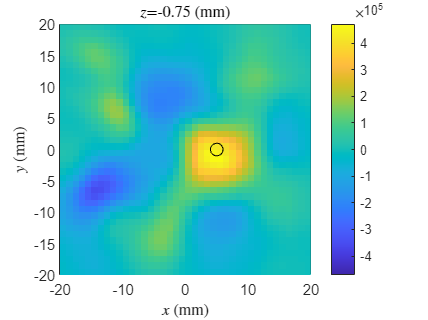

lambda = 1e-27;
R = (S' * S + lambda * eye(size(S,2))) \ S';

delta_sigma = R * delta_B;

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda R delta_sigma

#### Sparsity regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|\Delta \sigma \right\|}_1 \right\rbrace$$


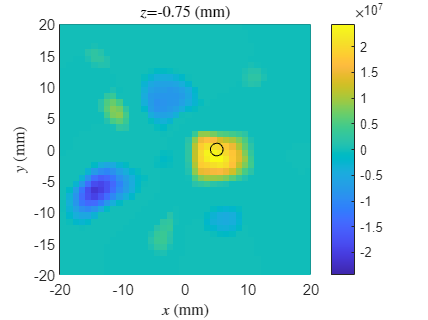

lambda = 1e-22;
beta = 1e-27;

reg{1}.lambda = lambda;
reg{1}.L = speye(size(S,2));

delta_sigma = L1Regularize(S,delta_B, reg, beta);

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda beta reg

#### Total variation regularization


$$\Delta \tilde{\sigma} =\textrm{argmin}\left\lbrace {\left\|S\Delta \sigma -\Delta B\right\|}_2^2 +\lambda {\left\|L_x \Delta \sigma \right\|}_1 +\lambda {\left\|L_y \Delta \sigma \right\|}_1 \right\rbrace$$


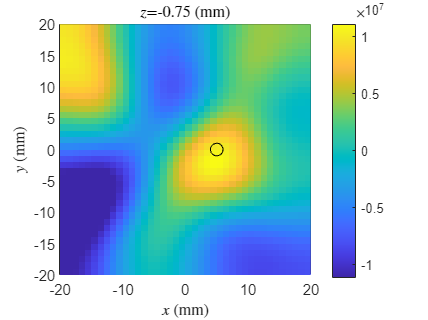

lambda = 1e-15;
beta = 1e-36;

reg{1}.lambda = lambda;
reg{1}.L = ElementsOperation('gradX', element_centers);
reg{2}.lambda = lambda;
reg{2}.L = ElementsOperation('gradY', element_centers);
reg{3}.lambda = lambda;
reg{3}.L = ElementsOperation('gradZ', element_centers);

delta_sigma = L1Regularize(S,delta_B, reg, beta);

displayReconstruction(delta_sigma, element_centers, defects)


clear lambda beta reg delta_sigma

#### Sparse Bayesian learning

b = 2;
Psi = ElementsOperation('BlockGroup', element_centers, b,b,1);

delta_sigma = BlockSBL(S, delta_B, 'StructureAwareMatrix',Psi, 'BlockLength',b^2, ...
    'ShareCorrelationMatrix',false, 'MaxIterations',20, 'Tolerance',1e-10);

Terminated after reaching maximum iterations


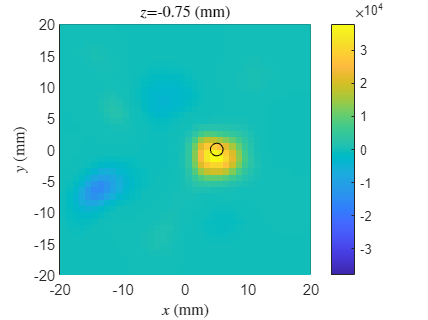


displayReconstruction(delta_sigma, element_centers, defects)


clear b Psi delta_sigma

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(delta_sigma, element_centers, defects)

c = real(-delta_sigma);

z = unique(element_centers(3,:));
z = sort(z, 'descend');

scale = 1e3;

global xylim
lim = [-xylim xylim] * scale;
b = (element_centers(1,2) - element_centers(1,1)) * scale;
pos = lim + [b -b] / 2;

figure('Position',[10 10 400 300*length(z)])
for k = 1:length(z)
    mask = element_centers(3,:) == z(k);
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    subplot(length(z),1,k)
    hold on
    imagesc(pos, pos, c_layer.', [-max(c) max(c)])
    colorbar
    axis square xy
    box on
    xlim(lim)
    ylim(lim)
    title(sprintf('$z$=%g (mm)',z(k)*scale), 'Interpreter','latex')
    xlabel('$x$ (mm)', 'Interpreter','latex')
    ylabel('$y$ (mm)', 'Interpreter','latex')

    for p = 1:length(defects)
        defect = defects{p};
        if ~(min(defect.z1, defect.z2) <= z(k) && z(k) <= max(defect.z1, defect.z2))
            continue
        end
        switch lower(defect.type)
            case 'rectangular'
                rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
                rectangle('Position', rect * scale)
            case 'circular'
                theta = linspace(0, 2*pi);
                x = defect.c_x + defect.d/2 * cos(theta);
                y = defect.c_y + defect.d/2 * sin(theta);
                plot(x * scale, y * scale, 'k')
            case 'polygonal'
                plot(defect.xs * scale, defect.ys * scale, 'k')
            otherwise
                error('Unknown defect shape "%s"', defect.type)
        end
    end
end

end